# Kinematic Vehicle Model

*by Ing. Denis Efremov*

## Introduction

The kinematic vehicle model is the simplest model of a car. It is used to model vehicle behavior when we do not need a precise vehicle dynamics. The kinematic model has no numerical problems around zero velocity (compare it with a single-track model in the next task), and we do not need to know tire characteristics to model a vehicle's behavior. Therefore it is mainly used to simulate a vehicle's behavior under low-speed conditions, for example, for autonomous parking assistance systems. However, this model works well when the vehicle does not operate on its handling limits (slow acceleration/deceleration or small steering angle)—it serves well for lane-keeping and path-tracking tasks for typical road operations, for example on a highway. To read more about possible usage of the kinematic vehicle model, we refer to [1,2,3].

## General "dynamics"

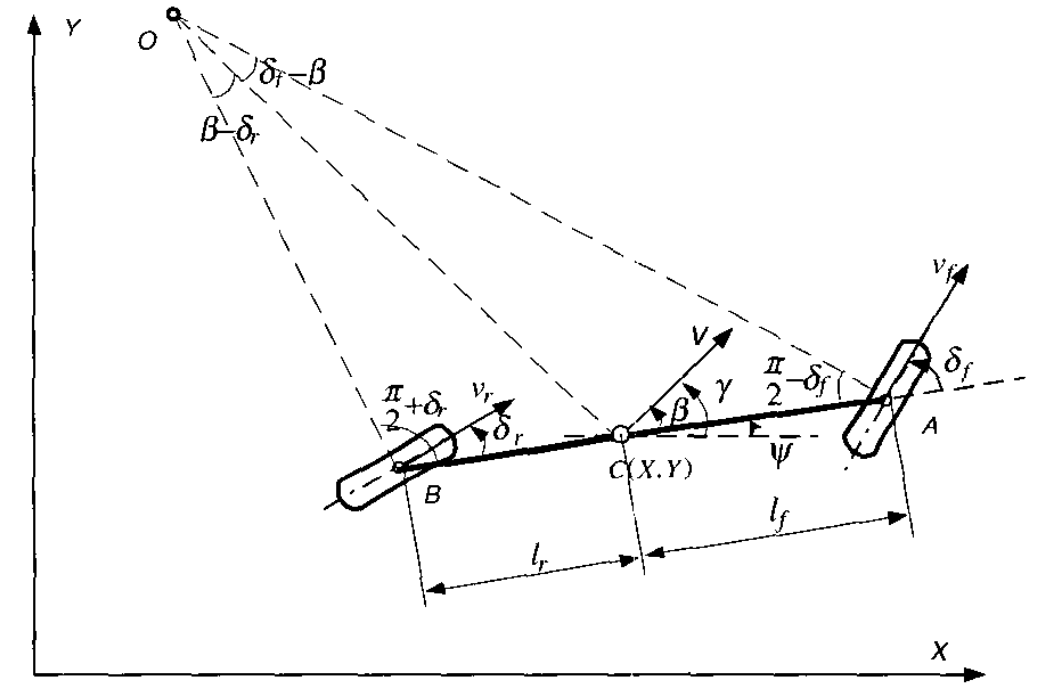Fig.1: Schematic model of a car. Source: [2]

The main parameters used in the kinematic model are distances between the center of gravity (CG) and wheels. Variable $l_{\rm f}$ stands for distance to the front, $l_{\rm r}$ - to the rear axles.

lf = 0.971; % m
lr = 1.566; % m

The kinematic model is called in such a way because, at its core, it has no dynamics at all. The general idea is to connect the steering angle (or angles) and sideslip angle of the vehicle, knowing the distances from the vehicle CG to both axles. 

*Task 1) Implement a function to calculate the sideslip angle of the vehicle at the end of this document.*

The vehicle's velocity can be a state (which is not in this case), or it could also be calculated from the travel velocity of wheels, which could be another input of the model. 

*Task 2) Implement a function to calculate the velocity of the vehicle as a function of the travel velocity of wheels at the end of this document.*

Those functions could be used as a core kinematic model. However, to work with vehicle trajectory, we have to augment the existing model with position coordinates and heading angle.

*Task 3) Assuming previously defined velocity and sideslip angle as model parameters implement a function, which will calculate position and heading angle derivatives according to the model parameters (CG's velocity and sideslip angle and distances from axles to the CG), previous states, and model inputs (wheels' travel velocity and steering angles).*

## Simulation ride tests

load('kinematic_model_test_data.mat','inputs')

% crop data from CarMaker
t_taken = 1:20000;

% trajectory of the vehicle will be stored here
xode = zeros(length(inputs.Data(t_taken,1)),1);
yode = zeros(length(inputs.Data(t_taken,1)),1);
psiode = zeros(length(inputs.Data(t_taken,1)),1);

% simulation time
time = inputs.Time(t_taken,1);

% ODE settings
options_ode = odeset('Maxstep', 10e-4, 'MaxOrder', 5, 'AbsTol', 1e-7);

% simulation
x_prev = [0, 0, 0]; % starting from zero point
xode(1) = x_prev(1);
yode(1) = x_prev(2);
psiode(1) = x_prev(3);
for k = 1:length(time)-1
    u = inputs.Data(k,:);
    [~, x] = ode15s(@kinematic_model_with_position, [time(k) time(k+1)], x_prev, options_ode, u, [lf, lr]);
    xode(k+1) = x(end,1);
    yode(k+1) = x(end,2);
    psiode(k+1) = x(end,3);
    x_prev = x(end,:);
end

% plotting
figure
set(groot, 'defaultAxesTickLabelInterpreter','latex'); set(groot, 'defaultLegendInterpreter','latex');
subplot(3,1,1)
plot(time, xode, 'linewidth', 2)
grid on
set(gca,'xticklabel',[])
ylabel('$x$ pos [m]', 'Interpreter','latex')
subplot(3,1,2)
plot(time, yode, 'linewidth', 2)
grid on
ylabel('$y$ pos [m]', 'Interpreter','latex')
set(gca,'xticklabel',[])
subplot(3,1,3)
plot(time, psiode, 'linewidth', 2)
grid on
ylabel('$\psi$ [rad]', 'Interpreter','latex')
xlabel('time [s]', 'Interpreter','latex')

% Definition of functions must be at the end of the script

function beta = sideslip_angle(df, dr, lf, lr)
    % inputs: df - steering angle of the front axle
    %         dr - steering angle of the rear axle
    %         lf - CG-front distance
    %         lr - CG-rear distance
    beta = atan((lr*tan(df)+lf*tan(dr))/(lf+lr)); 
end

function v = velocity(vf, vr, df, dr, beta)
    % inputs: vf - travel velocity of the front wheel 
    %         vr - travel velocity of the rear wheel
    %         df - steering angle of the front axle
    %         dr - steering angle of the rear axle
    %         beta - sideslip angle of the CG
    v =  (vf*cos(df)+vr*cos(dr))/(2*cos(beta)); 
end

function xdot = kinematic_model_with_position(time, states, inputs, params)
    % states: x - x coordinate
    %         y - y coordinate
    %         psi - heading angle
    % inputs: vf - travel velocity of the front wheel 
    %         vr - travel velocity of the rear wheel
    %         df - steering angle of the front axle
    %         dr - steering angle of the rear axle
    % params: lf - CG-front distance
    %         lr - CG-rear distance
    beta = sideslip_angle(inputs(3), inputs(4), params(1), params(2));
    v = velocity(inputs(1), inputs(2), inputs(3), inputs(4), beta);
    
    dx = v*cos(states(3)+beta);
    dy = v*sin(states(3)+beta); 
    dpsi = v*cos(beta)*(tan(inputs(3)-tan(inputs(4))))/(params(1)+params(2)); 
    
    xdot = [dx; dy; dpsi];
end


### References

[1] Kong, J., Pfeiffer, M., Schildbach, G., & Borrelli, F. (2015, June). Kinematic and dynamic vehicle models for autonomous driving control  design. In *2015 IEEE intelligent vehicles symposium (IV)* (pp. 1094-1099). IEEE.

[2] Wang, D., & Qi, F. (2001, May). Trajectory planning for a four-wheel-steering vehicle. In *Proceedings 2001 ICRA. IEEE International Conference on Robotics and Automation (Cat. No. 01CH37164)* (Vol. 4, pp. 3320-3325). IEEE.

[3] Song, Y., & Liao, C. (2016, July). Analysis and review of state-of-the-art automatic parking assist system. In *2016 IEEE International Conference on Vehicular Electronics and Safety (ICVES)* (pp. 1-6). IEEE.